# **PV**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_PvTk\PvTk1'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

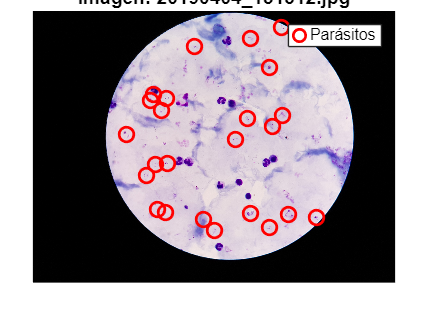

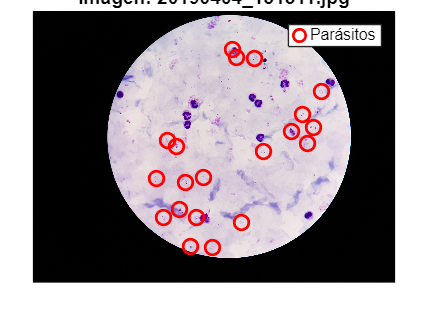

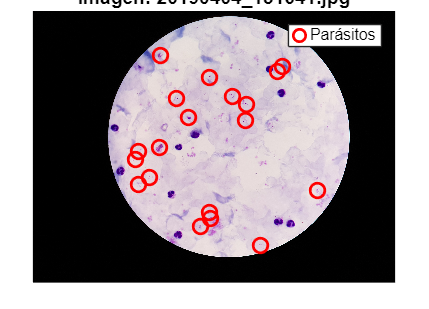

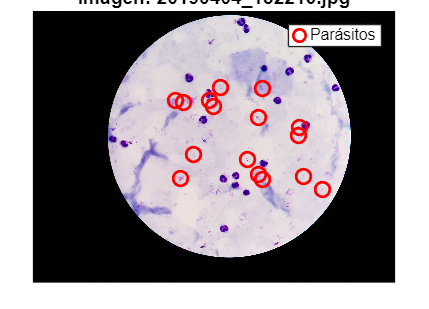

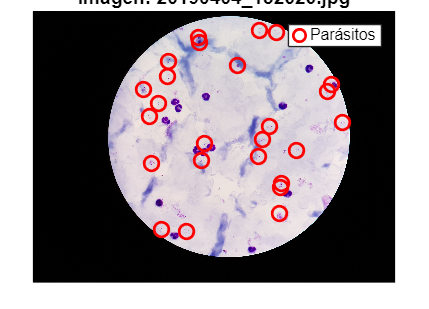

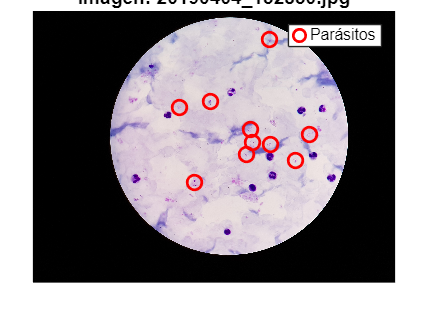

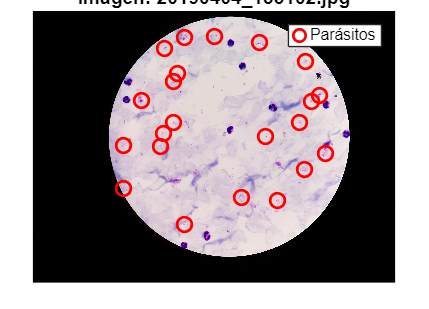

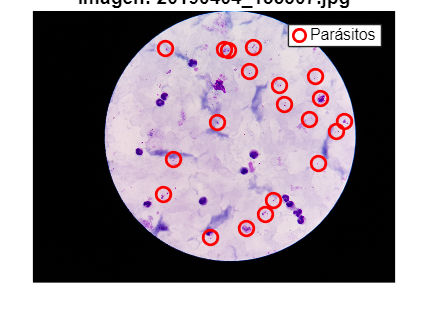

numero_de_wbc = 0

candidatos_a_wbc = 27

wbc_detectados = 0

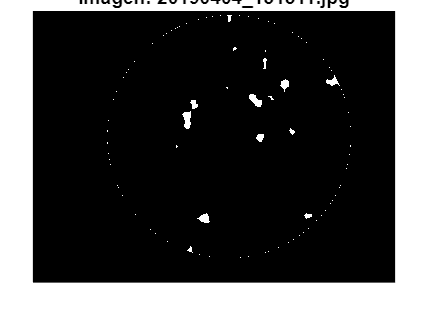

numero_de_wbc = 0

candidatos_a_wbc = 15

wbc_detectados = 0

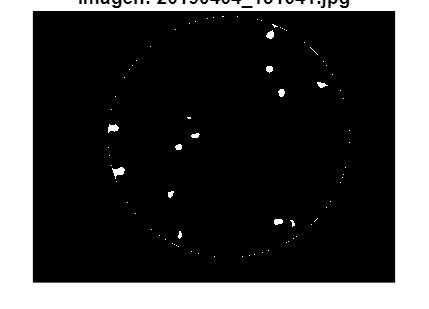

numero_de_wbc = 0

candidatos_a_wbc = 12

wbc_detectados = 0

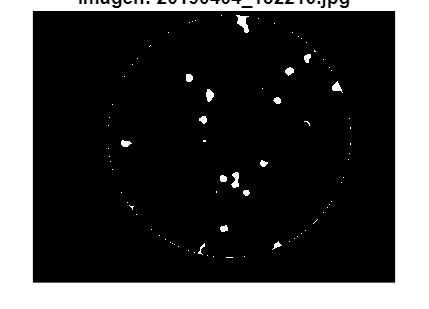

numero_de_wbc = 0

candidatos_a_wbc = 17

wbc_detectados = 0

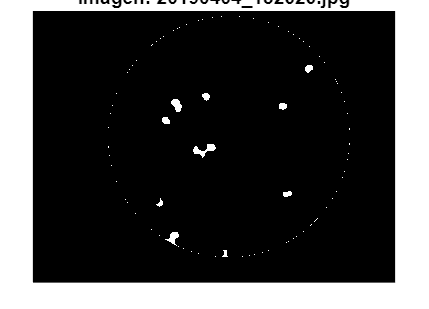

numero_de_wbc = 0

candidatos_a_wbc = 9

wbc_detectados = 0

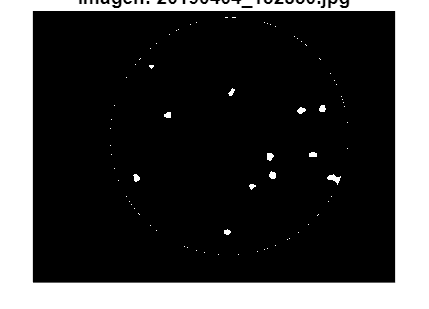

numero_de_wbc = 0

candidatos_a_wbc = 12

wbc_detectados = 0

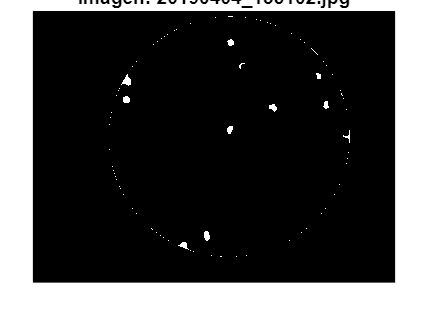

numero_de_wbc = 0

candidatos_a_wbc = 9

wbc_detectados = 0

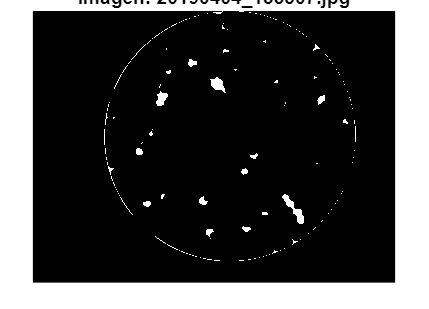

numero_de_wbc = 0

candidatos_a_wbc = 30

wbc_detectados = 0

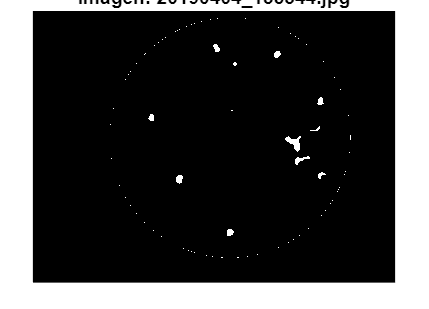

numero_de_wbc = 0

candidatos_a_wbc = 13

wbc_detectados = 0

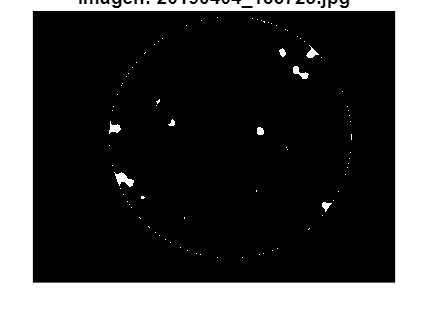

numero_de_wbc = 0

candidatos_a_wbc = 10

wbc_detectados = 0

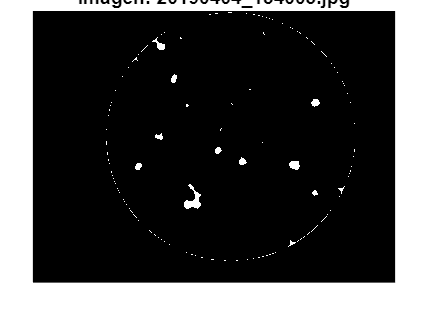

numero_de_wbc = 0

candidatos_a_wbc = 17

wbc_detectados = 0

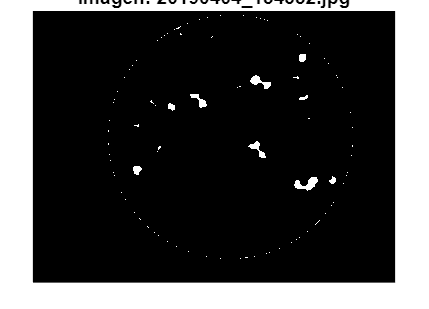

numero_de_wbc = 0

candidatos_a_wbc = 18

wbc_detectados = 0

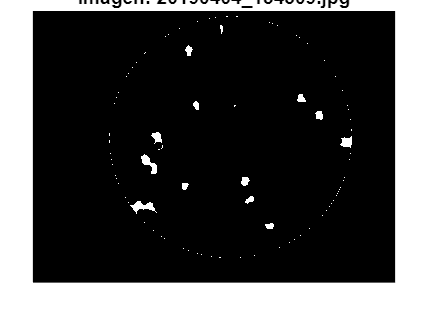

numero_de_wbc = 0

candidatos_a_wbc = 14

wbc_detectados = 0

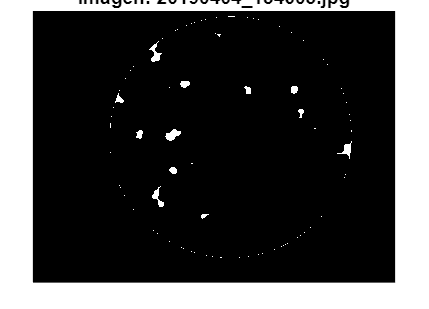

numero_de_wbc = 0

candidatos_a_wbc = 15

wbc_detectados = 0

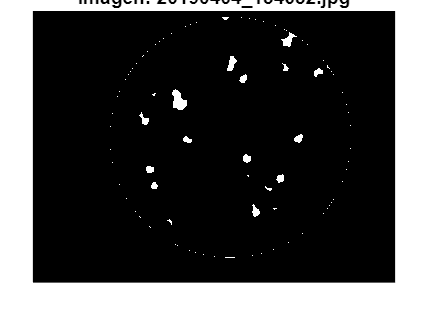

numero_de_wbc = 0

candidatos_a_wbc = 19

wbc_detectados = 0

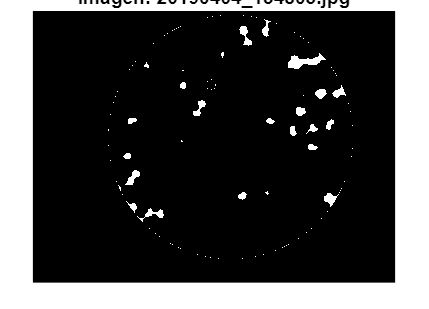

numero_de_wbc = 0

candidatos_a_wbc = 22

wbc_detectados = 0

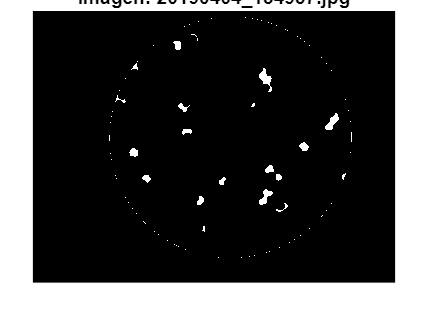

numero_de_wbc = 0

candidatos_a_wbc = 17

wbc_detectados = 0

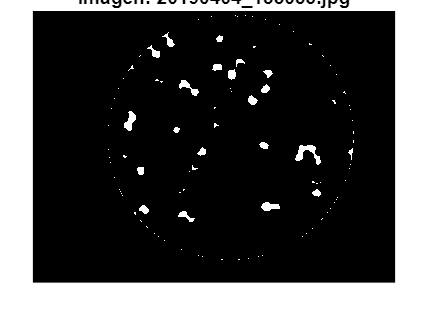

numero_de_wbc = 0

candidatos_a_wbc = 28

wbc_detectados = 0

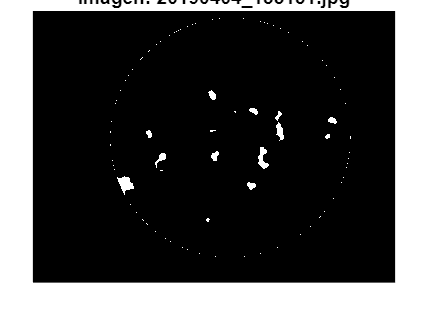

numero_de_wbc = 0

candidatos_a_wbc = 14

wbc_detectados = 0

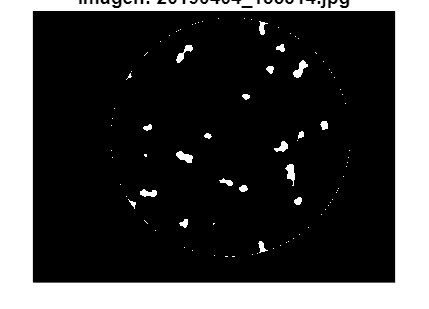

numero_de_wbc = 0

candidatos_a_wbc = 20

wbc_detectados = 0

total_wbc_reales = 0

total_candidatos = 338

total_wbc_detectados = 0

sensitivity = NaN

precision = 0

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parásitos');
    hold off;
end

## PARASITOS

### b) 4º Modelo Canny

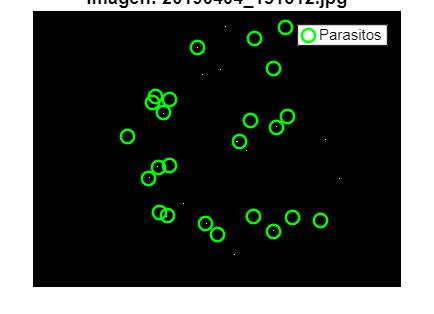

numero_de_parasitos = 24

candidatos_a_parasitos = 23

parasitos_detectados = 13

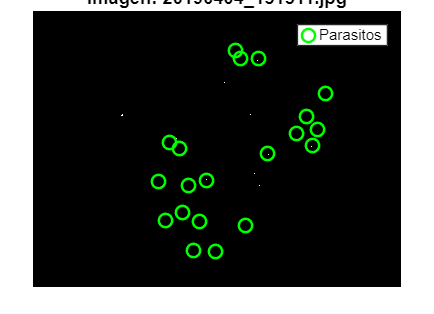

numero_de_parasitos = 20

candidatos_a_parasitos = 19

parasitos_detectados = 8

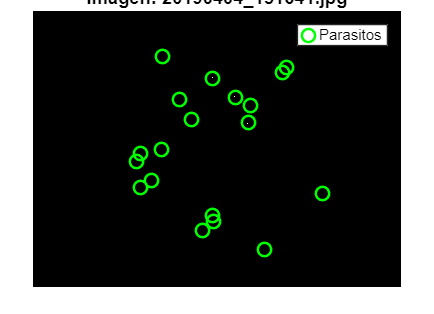

numero_de_parasitos = 19

candidatos_a_parasitos = 8

parasitos_detectados = 7

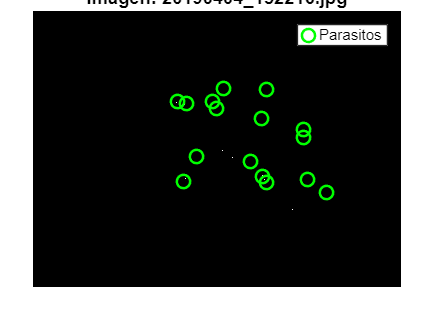

numero_de_parasitos = 16

candidatos_a_parasitos = 9

parasitos_detectados = 6

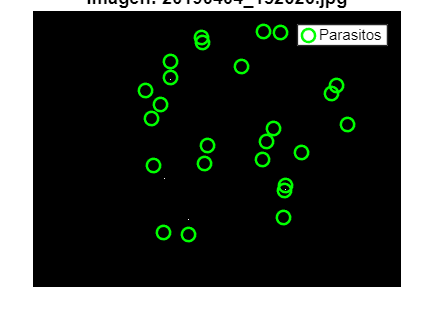

numero_de_parasitos = 25

candidatos_a_parasitos = 7

parasitos_detectados = 4

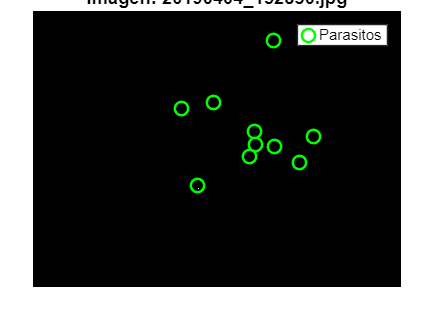

numero_de_parasitos = 10

candidatos_a_parasitos = 2

parasitos_detectados = 2

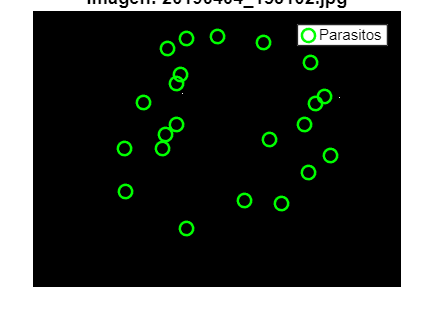

numero_de_parasitos = 22

candidatos_a_parasitos = 2

parasitos_detectados = 0

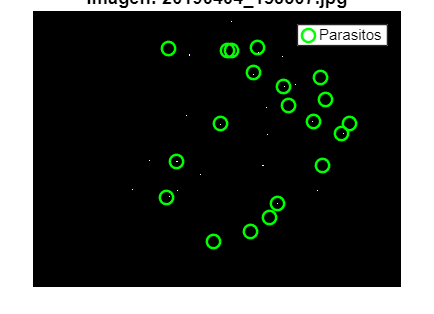

numero_de_parasitos = 20

candidatos_a_parasitos = 29

parasitos_detectados = 8

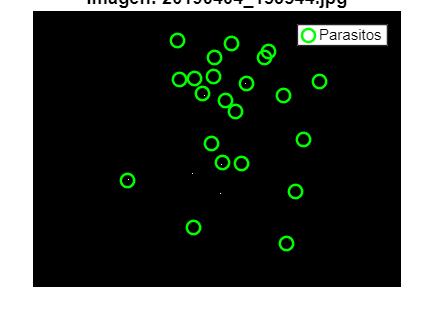

numero_de_parasitos = 22

candidatos_a_parasitos = 9

parasitos_detectados = 6

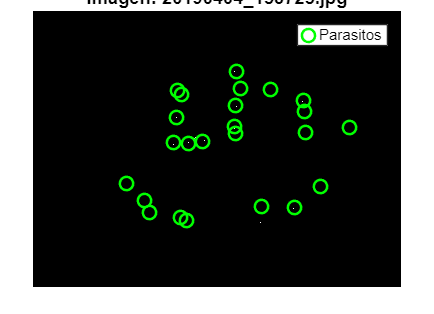

numero_de_parasitos = 24

candidatos_a_parasitos = 15

parasitos_detectados = 11

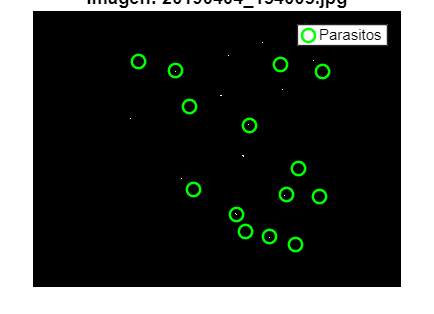

numero_de_parasitos = 14

candidatos_a_parasitos = 27

parasitos_detectados = 8

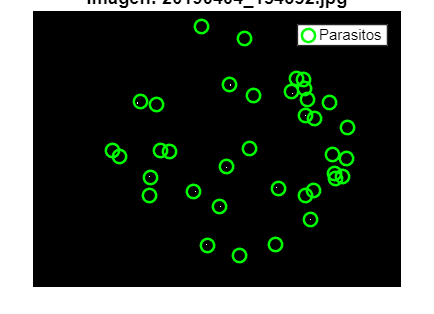

numero_de_parasitos = 37

candidatos_a_parasitos = 17

parasitos_detectados = 14

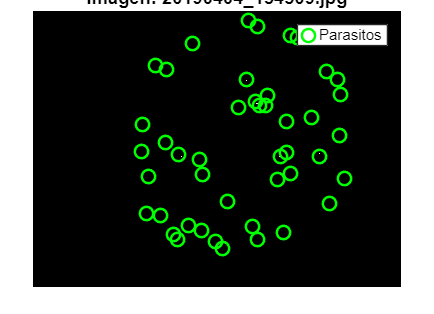

numero_de_parasitos = 45

candidatos_a_parasitos = 12

parasitos_detectados = 11

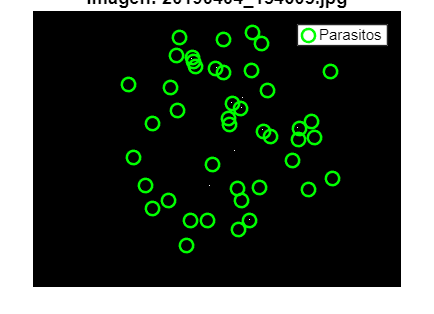

numero_de_parasitos = 43

candidatos_a_parasitos = 19

parasitos_detectados = 16

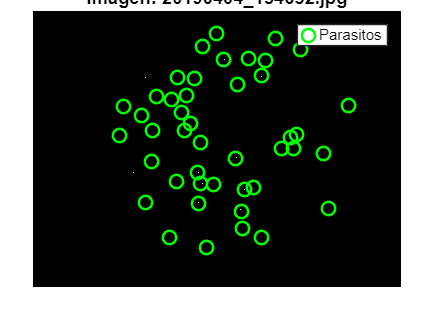

numero_de_parasitos = 44

candidatos_a_parasitos = 14

parasitos_detectados = 11

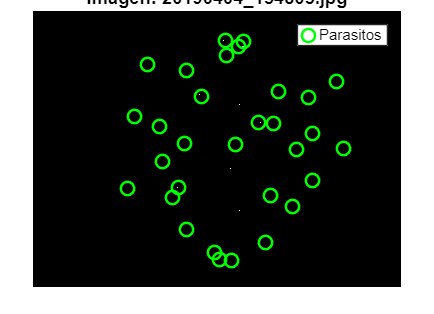

numero_de_parasitos = 31

candidatos_a_parasitos = 17

parasitos_detectados = 13

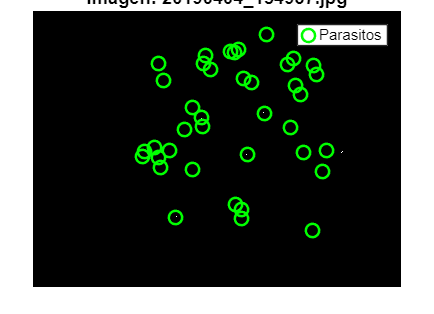

numero_de_parasitos = 39

candidatos_a_parasitos = 12

parasitos_detectados = 11

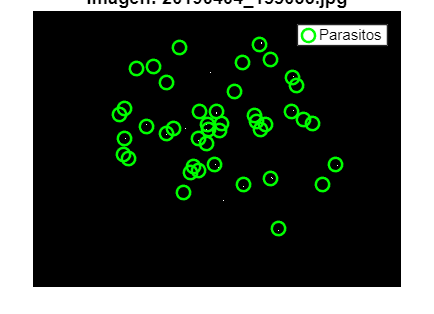

numero_de_parasitos = 43

candidatos_a_parasitos = 27

parasitos_detectados = 22

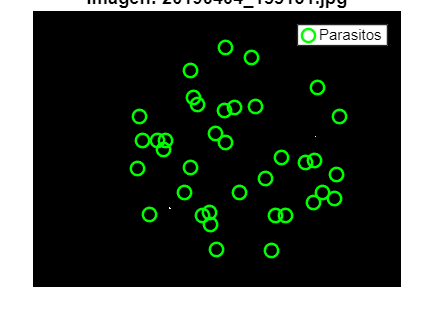

numero_de_parasitos = 37

candidatos_a_parasitos = 4

parasitos_detectados = 1

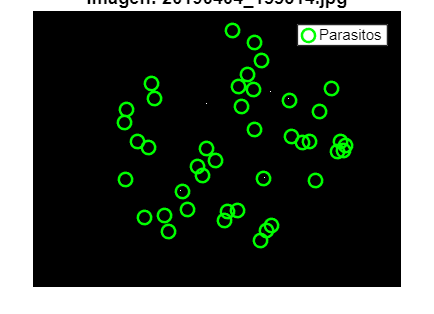

numero_de_parasitos = 42

candidatos_a_parasitos = 5

parasitos_detectados = 3

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
  
    % Pasarlo a escala de grises
    I_gray = rgb2gray(I);

    % Quitar ruido
    I_sinruido=medfilt2(I_gray, [3 3]);
    
    % Detección de bordes
    BW = edge(I_sinruido, 'Canny',[0.05 0.4]);
    
    % Cerrar los contornos
    BW = imclose(BW, strel('disk', 40));
    
    % Revisar las propiedades
    CC = bwconncomp(BW,8);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    stats = regionprops(CC,properties);
    
    % Define umbrales de área
    area_min = 200;
    area_max = max([stats.Area]); 
    
    % Crear nueva máscara basada en área
    BW_filtrada_area = false(size(BW));
    labeled_area = labelmatrix(CC);
    
    for c = 1:length(stats)
        area = stats(c).Area;
     
        if area >= area_min && area <= area_max
            BW_filtrada_area = BW_filtrada_area | (labeled_area == c);
        end
    end
    
    % Reemplazar máscara con la filtrada por área
    globulos_blancos = BW_filtrada_area;

    % Mascara de parasitos
    mascara_parasitos=BW-globulos_blancos;

    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');hold on;

    % % === Detección de círculos (parásitos) ===
    % [centers, radii] = imfindcircles(mascara_parasitos, [1 4], ...
    %     'ObjectPolarity','dark', 'Sensitivity', 0.93, 'EdgeThreshold', 0.1);
    % 
    % % === Mostrar resultados ===
    % figure; imshow(I); hold on;
    % viscircles(centers, radii, 'Color','r');hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
  
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'go', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parasitos');
    hold off;

    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)
    n=8;
    % Candidatos a parasitos
    CC_2 = bwconncomp(mascara_parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end


% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 577

total_candidatos

total_candidatos = 277

total_parasitos_detectados

total_parasitos_detectados = 175


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 30.3293

precision=(TP/(TP+FP))*100

precision = 63.1769